fs = 10e6; % Baseband Sampling Rate (65105 to 61.44e6 Hz)
frame_size = 4096; % Samples per Each Frame (< 2^20)
% Transmitter Parameters
tx_fc = 325e6; % Set Transmitter Center Frequency 
% (AD9363: 325-3800MHz) (AD9364: 70-6000MHz)
tx_gain = -30; % Set Transmitter Attenuation as a Negative Gain 
% (-89.75 to 0 dB)
tx_address = 'usb:0'; % Set Transmitter Identification Number
% Receiver Parameters
rx_fc = 325e6; % Set Receiver Center Frequency 
% (AD9363: 325-3800MHz) (AD9364: 70-6000MHz)
rx_gain = 20; % Set Receiver Gain (-4dB to 71dB)
rx_address = 'usb:0'; % Set Receiver Identification Number
% Initialize ADALM-PLUTO
dev = sdrdev('Pluto'); % Create Radio Object for ADALM-PLUTO
% setupSession(dev)
% configurePlutoRadio('AD9363'); % Configure ADALM-PLUTO Radio Firmware
% Define Transmitter Object
tx = sdrtx('Pluto','RadioID',tx_address); % CreateTransmitterSystem Object
tx.CenterFrequency = tx_fc; % Set Transmitter Center Frequency
tx.Gain = tx_gain; % Set Transmitter Gain
tx.BasebandSampleRate = fs; % Set Baseband Sampling Rate
% Define Receiver Object
rx = sdrrx('Pluto','RadioID',rx_address); % Create Receiver System Object
rx.CenterFrequency = rx_fc; % Set Receiver Center Frequency
rx.BasebandSampleRate = fs; % Set Baseband Sampling Rate 
rx.SamplesPerFrame = frame_size; % Samples per Each Frame (< 2^20)
rx.GainSource = 'Manual'; % AGC Settings
rx.Gain = rx_gain; 
rx.OutputDataType = 'double'; % Output Data Type
stop_time = 120;

% Transmit Repeat
f_offset = 1e6;
t = (0:2^14-1)'/fs;
sin_wave = exp(1j*2*pi*f_offset*t);
tx.transmitRepeat(sin_wave);

## Establishing connection to hardware. This process can take several seconds.


## Waveform transmission has started successfully and will repeat indefinitely. 
## Call the release method to stop the transmission.


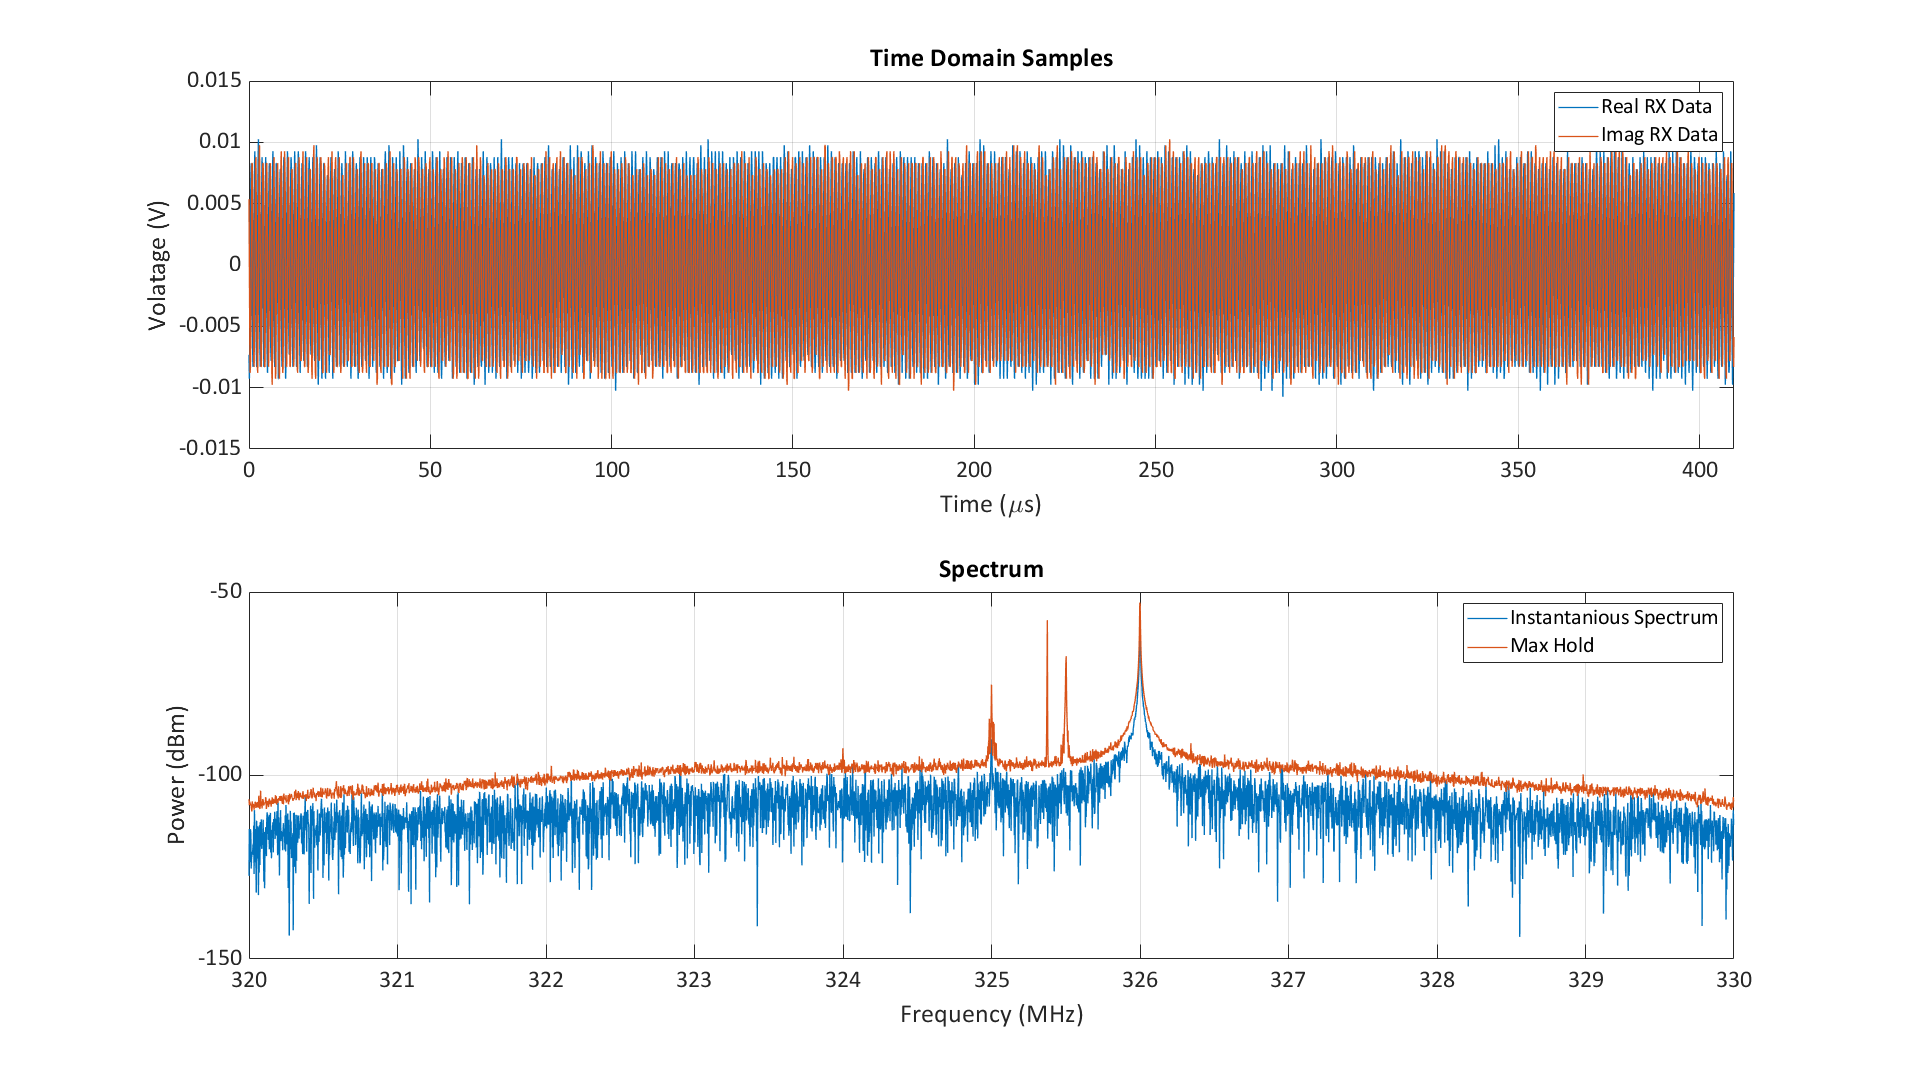

## Establishing connection to hardware. This process can take several seconds.


tic;

%% Plot Template

freq = (0:frame_size-1)'/frame_size*fs - fs/2 + rx_fc;
time = (0:frame_size-1)'/fs;

rx_data_real = zeros(size(freq));
rx_data_imag = zeros(size(freq));
rx_fft_dBm = zeros(size(freq));
rx_fft_dBm_max = zeros(size(freq))-300;

fig1 = figure('units','normalized','outerposition',[0 0 1 1]);

sp1 = subplot(2,1,1);

p1 = plot(time*1e6, rx_data_real, 'Parent', sp1, 'DisplayName','Real RX Data', 'LineWidth' , 1);
hold all
p2 = plot(time*1e6, rx_data_real, 'Parent', sp1, 'DisplayName','Imag RX Data', 'LineWidth' , 1);
sp1.FontName = 'Calibri';
sp1.FontSize = 18;

p1.YDataSource = 'rx_data_real';
p2.YDataSource = 'rx_data_imag';

xlabel('Time (\mus)','FontSize',24,'FontName','Calibri')
ylabel('Volatage (V)','FontSize',24,'FontName','Calibri')
title('Time Domain Samples','FontSize',24,'FontName','Calibri')
xlim([min(time), max(time)]*1e6)
legend show
grid on

sp2 = subplot(2,1,2, 'FontName','Calibri','FontSize',18);
p3 = plot(freq/1e6, rx_fft_dBm,'Parent', sp2, 'DisplayName','Instantanious Spectrum', 'LineWidth' , 1);
hold all
p4 = plot(freq/1e6, rx_fft_dBm_max, 'Parent', sp2, 'DisplayName','Max Hold', 'LineWidth' , 1);

p3.YDataSource = 'rx_fft_dBm';
p4.YDataSource = 'rx_fft_dBm_max';

sp2.FontName = 'Calibri';
sp2.FontSize = 18;

xlabel('Frequency (MHz)','FontSize',24,'FontName','Calibri')
ylabel('Power (dBm)','FontSize',24,'FontName','Calibri')
title('Spectrum','FontSize',24,'FontName','Calibri')
legend show
grid on
R = 50;
while toc < stop_time
    rx_data = rx();
    rx_data_real = real(rx_data);
    rx_data_imag = imag(rx_data);
    rx_data_no_dc = rx_data - mean(rx_data);
 
    rx_fft = fftshift(fft(rx_data)/frame_size);
    rx_fft_dBm = 10*log10(abs(rx_fft).^2/(2*R)*1000) - rx_gain;
    rx_fft_dBm_max = max(rx_fft_dBm_max, rx_fft_dBm);
    refreshdata
    drawnow
end

%

% ylim([-70 0])
% xlim([-fs/2/1e6 fs/2/1e6])
%

function [spect, freq] = spectral_density(x, fs, n_fft)
freq = (0:n_fft-1)/n_fft * fs - fs/2;
Xf = fftshift(fft(x, n_fft))/n_fft;
R = 50;
spect =  10 * log10(abs(Xf).^2/(2*R)) + 30;  
end